## Load the data

% MODEL = 'SVM';

if strcmp(DATA_TYPE,'highSI')
    data_real = readmatrix(strcat('..\Data\',MODEL,'\real_data_39_highSI.txt'));

    data_predicted = readmatrix(strcat('..\Data\',MODEL,'\predicted_data_39_highSI.txt'));
else
    data_real = readmatrix(strcat('..\Data\',MODEL,'\real_data_39_lowSI.txt'));

    data_predicted = readmatrix(strcat('..\Data\',MODEL,'\predicted_data_39_lowSI.txt'));

end

## Preprocess the data

data_real = data_real(1:5:end);

data_predicted = data_predicted(1:5:end);

for i = 1:length(data_predicted)
    if data_predicted(i) <= 0
        data_predicted(i) = data_real(i);
    end
end

## Fit the data to the gamma-gamma distribution

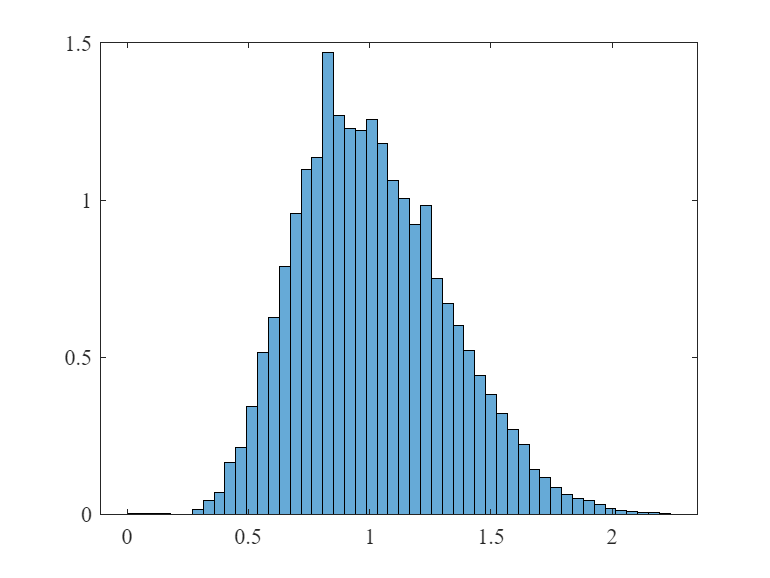

histo = histogram(data_real, 50, 'Normalization','pdf');

% edge = histo.BinEdges;
% x_value = zeros(1,length(edge)-1);
% for i = 1:length(edge)-1
%     x_value(i) = (edge(i+1) + edge(i)) / 2;
% end
% x_value;
% y_value = histo.Values;

% [den, xi] = ksdensity(hp);
% xi = xi(xi > 0);
% den = den(xi > 0);

## Log-normal pdf

pdf_ln_fit = @(sigma_r, h_a) 1 ./ (sqrt(2*pi) .* sigma_r .* h_a) ...
            .* exp(- (log(h_a) + sigma_r.^2 ./2).^2 ./ (2 .* sigma_r.^2));

% sigma_r0 = 0.2;
% sigma_r = lsqcurvefit(pdf_ln_fit,sigma_r0,x_value,y_value);

%% Histogram and fit the data
p_ln = lognfit(data_real);

Rytov = p_ln(2);

Rytov;

## Plot the fit line

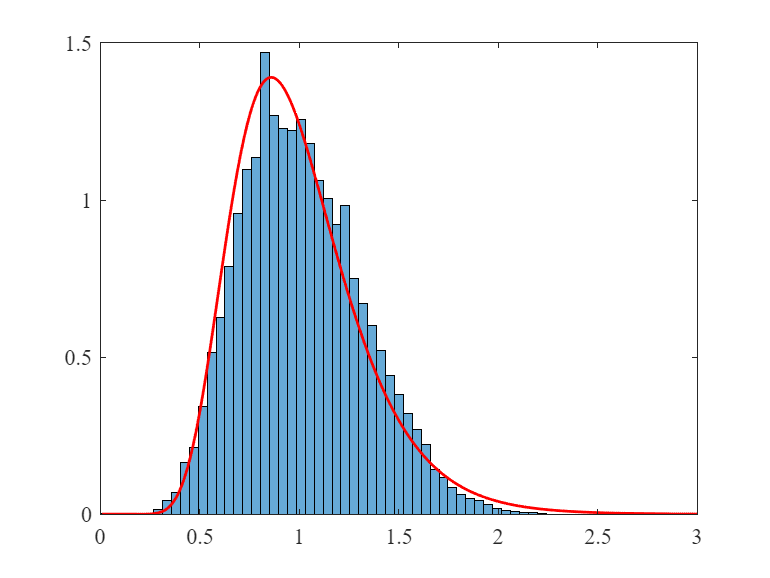

hold on
x = 0:0.01:3;
y2 = pdf_ln_fit(Rytov,x);
% plot(x,y,'r','LineWidth',1.5);
plot(x,y2,'r','LineWidth',1.5);
hold off
xlim([0 3]);